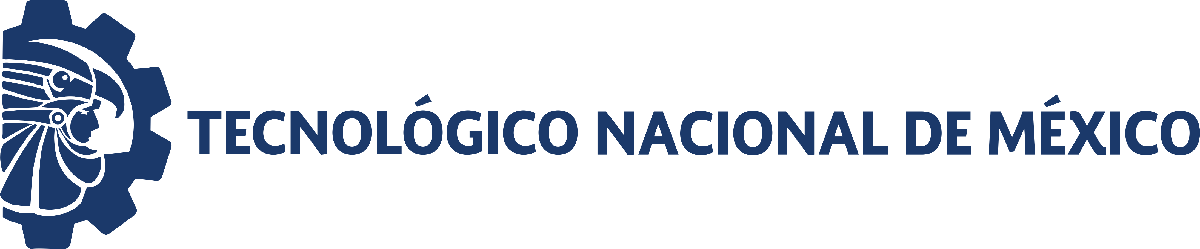                                 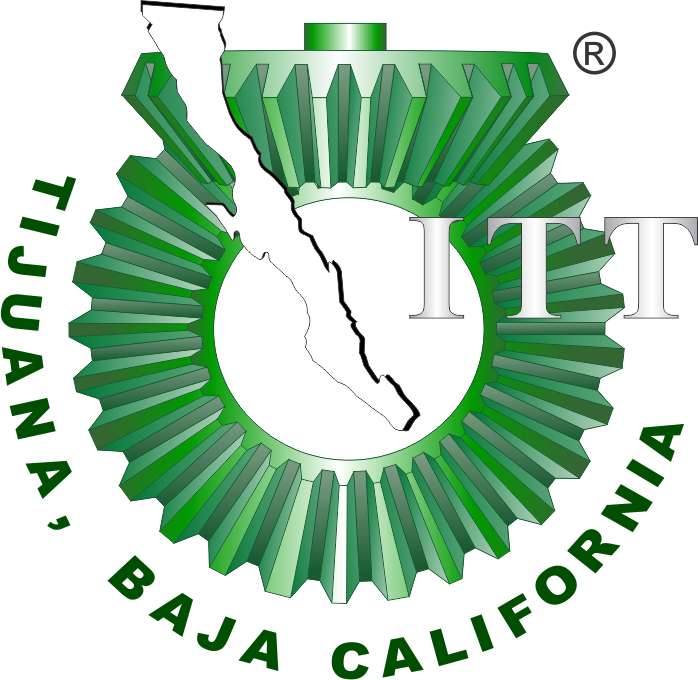

# Práctica: Liberación controlada de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

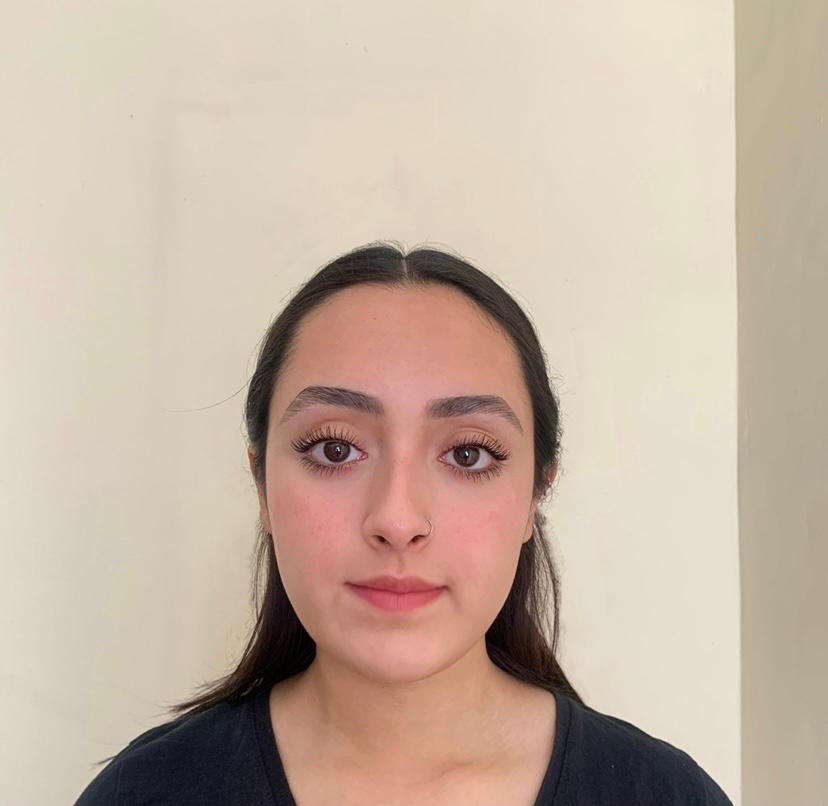

Nombre del alumno: **Maria Fernanda Antunez Rubio**

Número de control: **22211745**

Correo institucional: **L22211745@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

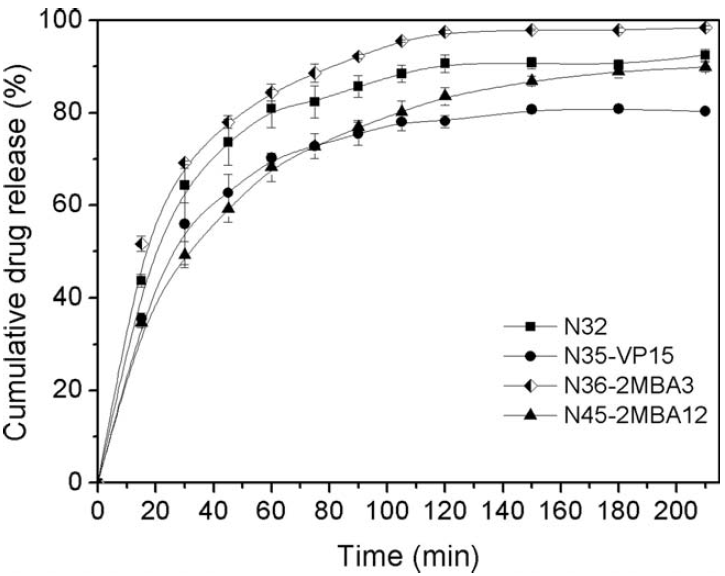

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $

Eureqa: $$x(t) = \frac{p_1 t}{p_2 + t}$$

Eureqa EDO= $$\dot{x} = p_1 - p_2 x$$

## Datos experimentales

    t [min]     N45        N32        N35        N36  
    _______    ______    _______    _______    _______

        0           0    0.11834    0.11834    0.35503
       15      33.846     43.787     35.621     51.953
       30      48.402      64.26     55.976     69.112
       45      59.172     73.728     62.722      77.87
       60      68.284     80.828     70.059      84.26
       75      72.781      82.13     72.663     88.521
       90      77.041     85.562     75.266     92.308
      105      80.355     88.166     77.988     95.385
      120      83.787     90.296     78.107     97.278
      150      86.982     90.769     80.592     97.751
      180      88.994     90.414     80.828     97.633
      210      89.822     92.189     80.473     98.343



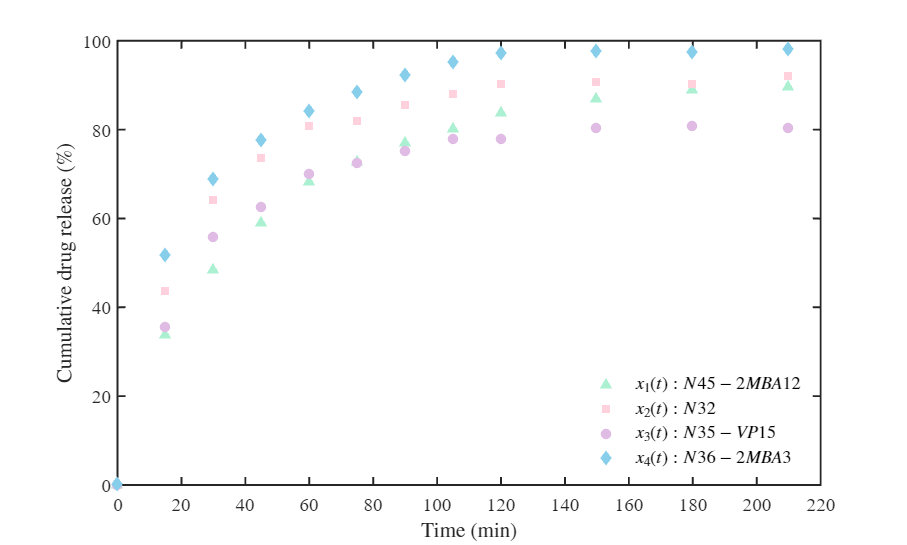

--> Gráfica exportada exitosamente como: data.pdf


clc; clear; close all; warning('off','all')
[t,x1,x2,x3,x4] = getdata('p3Data.csv'); plotdata(t,x1,x2,x3,x4);

## Regresión no lineal, bioestadistios y experimentación in silico

labels = {'x1(t):N45-2MBA12', 'x2(t):N32', 'x3(t):N35-VP15', 'x4(t):N36-2MBA3'};
xo = [x1,x2,x3,x4]; s = size(xo);


### Función de Pepas

n0 = 0.1; k0 = 0.1; xp = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el hidrogel: ', string(labels(i))]);
    mdl = peppas(t,xo(:,i),[n0;k0]);
    xp(:,i) = mdl.Fitted; disp('');
end

    "Resultados para el hidrogel: "    "x1(t):N45-2MBA12"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    _______    __________________    __________

      {'k'}          17.3       2.2572     5.0293     12.271      22.33      1.71e-05
      {'n'}       0.32114     0.027772    0.06188    0.25926    0.38302    4.1358e-07

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9777
Suma residual de cuadrados:     177.7360
Criterio de inf. Akaike (AICc): 71

    "Resultados para el hidrogel: "    "x2(t):N32"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        30.629       4.2502        9.47     21.159     40.099    2.9042e-05
      {'n'}       0.21855     0.030036    0.066925    0.15162    0.28547    2.6752e-05

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9638
Suma residual de cuadrados:     291.4087
Criterio de inf. Akaike (AICc)

    "Resultados para el hidrogel: "    "x3(t):N35-VP15"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        24.785       3.7942       8.454     16.331     33.239    6.6193e-05
      {'n'}       0.23563     0.033037    0.073611    0.16202    0.30924    3.1709e-05

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9589
Suma residual de cuadrados:     263.7334
Criterio de inf. Akaike (AICc)

    "Resultados para el hidrogel: "    "x4(t):N36-2MBA3"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        34.457       3.8122      8.4941     25.963     42.951    3.9819e-06
      {'n'}       0.20881     0.023989    0.053451    0.15536    0.26226    5.5818e-06

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9757
Suma residual de cuadrados:     218.0902
Criterio de inf. Akaike (AICc)

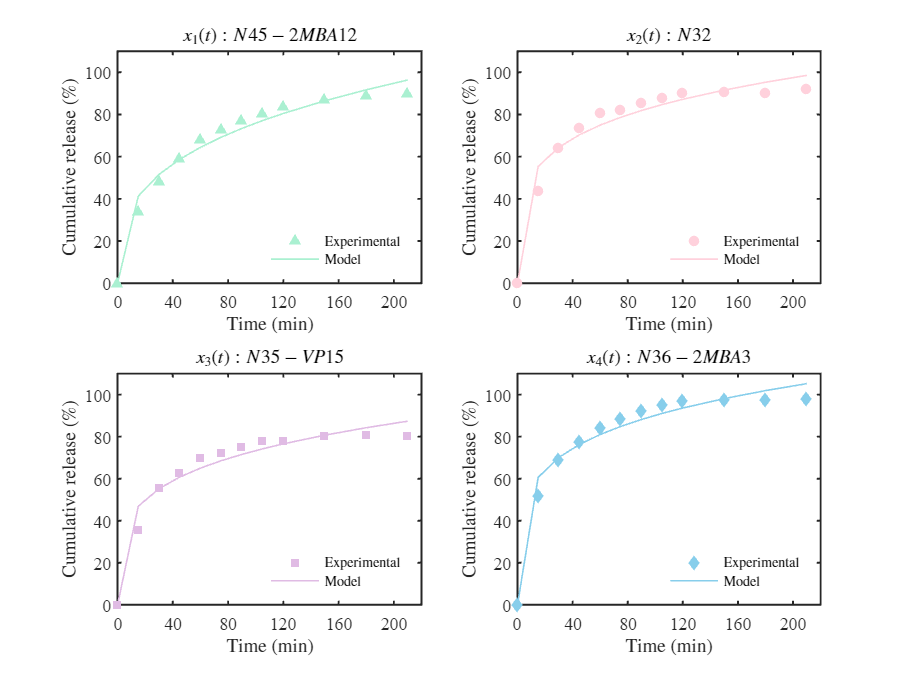

plotresults(t,xo,xp)

### Función farmacocinética de primer orden

beta0 = 100; k0 = 0.01; xfc = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel ',string(labels(i))])
    mdl = farmacocinetica(t,xo(:,i),[beta0;k0]);
    xfc(:,i) = mdl.Fitted; disp('');
end

    "Resultados para el Hidrogel "    "x1(t):N45-2MBA12"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       88.114       1.3529       3.0145      85.099      91.128    1.7731e-14
     {'k'   }     0.025538    0.0013675    0.0030469    0.022491    0.028585    4.1889e-09

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9926
Suma residual de cuadrados:     58.6747
Criterio de inf

    "Resultados para el Hidrogel "    "x2(t):N32"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    ________    _________    ____________________    __________

     {'beta'}       89.745     0.81936       1.8256       87.92      91.571    9.8646e-17
     {'k'   }     0.040635    0.001751    0.0039015    0.036733    0.044536    4.9934e-10

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9954
Suma residual de cuadrados:     37.2757
Criterio de inf. Ak

    "Resultados para el Hidrogel "    "x3(t):N35-VP15"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       79.457      0.68864       1.5344      77.923      80.991    5.8638e-17
     {'k'   }     0.037435    0.0014526    0.0032367    0.034199    0.040672    1.7787e-10

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9962
Suma residual de cuadrados:     24.3715
Criterio de inf

    "Resultados para el Hidrogel "    "x4(t):N36-2MBA3"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}      95.976        1.3782       3.0708      92.905      99.047    9.0881e-15
     {'k'   }     0.04227     0.0029382    0.0065467    0.035723    0.048817    5.2192e-08

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9879
Suma residual de cuadrados:     109.1682
Criterio de in

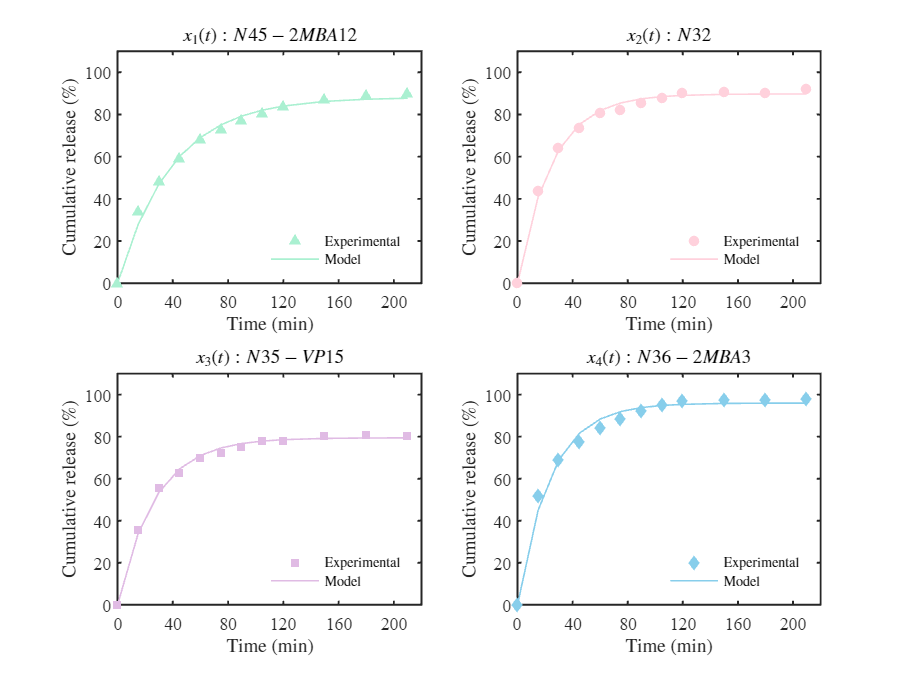

plotresults(t,xo,xfc); exportgraphics(gcf, 'farmacocinetica.pdf', 'ContentType', 'vector');

### Eureqa: Función en el tiempo

beta0 = 100; k0 = 0.01; xfc = zeros(s(1),s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel ',string(labels(i))])
    mdl = eureqa(t,xo(:,i),[beta0;k0]);
    xfc(:,i) = mdl.Fitted; disp('');
end

    "Resultados para el Hidrogel "    "x1(t):N45-2MBA12"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate      SE         MoE              CI95             Pvalue  
    __________    ________    _______    ________    __________________    __________

     {'beta'}       11.13     0.26803     0.59721     10.532     11.727    1.5726e-12
     {'k'   }      0.3313     0.02314    0.051559    0.27974    0.38286    5.4658e-08

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9949
Suma residual de cuadrados:     40.5855
Criterio de inf. Akaike (AICc): 54.

    "Resultados para el Hidrogel "    "x2(t):N32"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

     {'beta'}      14.551      0.26109     0.58175     13.969     15.132    8.3906e-14
     {'k'   }      0.5745     0.022541    0.050224    0.52427    0.62472    1.9839e-10

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9952
Suma residual de cuadrados:     38.5110
Criterio de inf. Akaike (AICc):

    "Resultados para el Hidrogel "    "x3(t):N35-VP15"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate      SE         MoE             CI95             Pvalue  
    __________    ________    _______    ________    _________________    __________

     {'beta'}      12.475     0.27081      0.6034    11.872     13.079    5.5958e-13
     {'k'   }     0.47869     0.02338    0.052093    0.4266    0.53078    1.7061e-09

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9935
Suma residual de cuadrados:     41.4306
Criterio de inf. Akaike (AICc): 54.2572

    "Resultados para el Hidrogel "    "x4(t):N36-2MBA3"



Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    _______    __________________    __________

     {'beta'}      15.739      0.12913    0.28772     15.451     16.027    3.3905e-17
     {'k'   }     0.62619     0.011148    0.02484    0.60136    0.65103    7.7586e-14

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9990
Suma residual de cuadrados:     9.4202
Criterio de inf. Akaike (AICc): 36.4

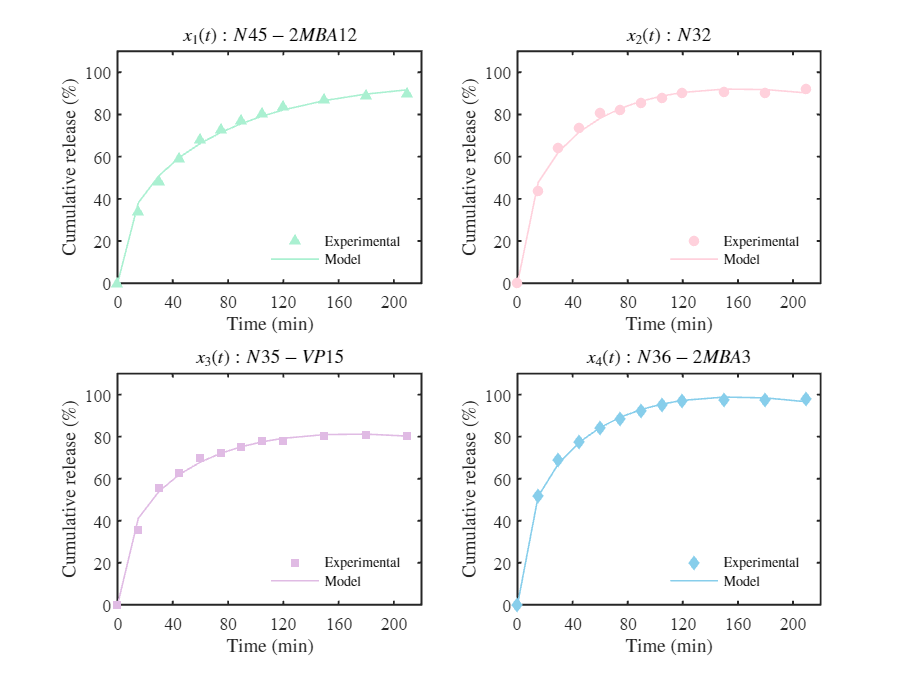

plotresults(t,xo,xfc); exportgraphics(gcf, 'funcioneneltiempo.pdf', 'ContentType', 'vector');

### Eureqa: Farmacocinética de primer orden


p1_0 = 0.5; 
p2_0 = 0.1; 
xfc = zeros(size(xo)); 

for i = 1:4
    fprintf('\nResultados para el Hidrogel %s\n', string(labels(i)));
    
    mdl = fit_ode_model(t, xo(:,i), [p1_0; p2_0]);
    
    xfc(:,i) = mdl.Fitted; 
    disp(''); 
end


Resultados para el Hidrogel x1(t):N45-2MBA12


Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'p1'}        2.2503     0.096682      0.21542      2.0348      2.4657     4.851e-10
      {'p2'}      0.025538    0.0013674    0.0030468    0.022491    0.028585    4.1878e-09

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9926
Suma residual de cuadrados:     58.6741
Criterio de inf


Resultados para el Hidrogel x2(t):N32


Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE              CI95              Pvalue  
    __________    ________    _________    _________    ___________________    __________

      {'p1'}        3.6415      0.13824      0.30802     3.3335      3.9495    1.4325e-10
      {'p2'}      0.040573    0.0017424    0.0038824    0.03669    0.044455    4.8303e-10

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9954
Suma residual de cuadrados:     36.9567
Criterio de inf. Ak


Resultados para el Hidrogel x3(t):N35-VP15


Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE              CI95              Pvalue  
    __________    ________    _________    _________    ___________________    __________

      {'p1'}        2.9696       0.1001      0.22304     2.7465      3.1926    4.4263e-11
      {'p2'}      0.037369    0.0014444    0.0032184    0.03415    0.040587    1.7119e-10

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9962
Suma residual de cuadrados:     24.1282
Criterio de inf. Ak


Resultados para el Hidrogel x4(t):N36-2MBA3


Cantidad de datos (n):          12
Cantidad de parámetros (k):     2
Grados de libertad (DFE):       10
Significancia (alpha):          0.05
Valor t-student:                2.2281
-------------------------------------------------------------
Coefficients:
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

      {'p1'}        4.0395      0.24795      0.55246       3.487      4.5919    1.5768e-08
      {'p2'}      0.042076    0.0029049    0.0064726    0.035604    0.048549    4.8907e-08

-------------------------------------------------------------
Bondad de Ajuste:
R-cuadrada ordinaria:           0.9881
Suma residual de cuadrados:     107.1650
Criterio de in

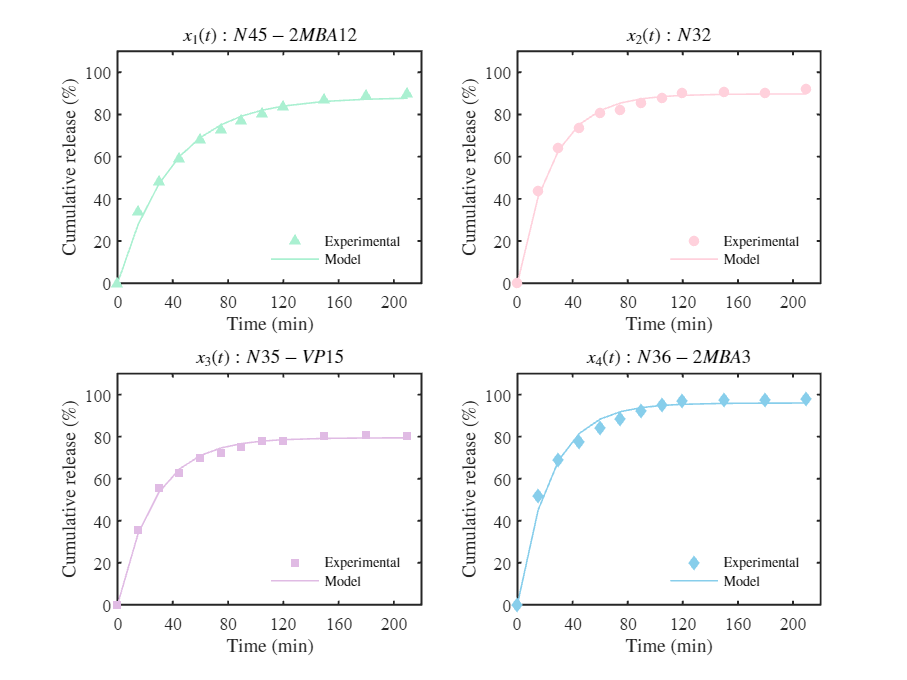

plotresults(t, xo, xfc); 
exportgraphics(gcf, 'eureqafarmocinetica.pdf', 'ContentType', 'vector');

## Funciones

### Datos experimentales

function [t, x1, x2, x3, x4] = getdata(data)
    sys = readmatrix(data);
    t = sys(:,1); x1 = sys(:,2); x2 = sys(:,3); x3 = sys(:,4); x4 = sys(:,5);
    T = array2table([t,x1,x2,x3,x4],'VariableNames',{'t [min]','N45','N32','N35','N36'}); disp(T);
end

function plotdata(t, x1, x2, x3, x4)
    set(figure(), 'Color', 'w')
    FS = 12;
    set(gcf, 'Units', 'Centimeters', 'Position', [1, 1, 20, 12])
    hold on, box on, grid off;
    nombresLeyenda = {'$x_1(t): N45-2MBA12$', '$x_2(t): N32$', '$x_3(t): N35-VP15$', '$x_4(t): N36-2MBA3$'};
    marcadores = {'^', 's', 'o', 'd'}; 
    colores = {'#AAF0D1', '#FFD1DC', '#E0BBE4', '#87CEEB'}; 
    variables_x = {x1, x2, x3, x4};
    
    for i = 1:4
        plot(t, variables_x{i}, ...
            'LineStyle', 'none', ...
            'Marker', marcadores{i}, ...
            'MarkerFaceColor', colores{i}, ...
            'MarkerEdgeColor', colores{i}, ...
            'MarkerSize', 6);
    end

    xlabel('Time (min)', 'Interpreter', 'Latex', 'FontSize', FS)
    ylabel('Cumulative drug release (\%)', 'Interpreter', 'Latex', 'FontSize', FS)
    
    xlim([0, 220]);
    ylim([0, 100]);
    xticks(0:20:220);
    yticks(0:20:100);
    
    legend(nombresLeyenda, 'Location', 'southeast', 'Box', 'off', ...
           'Interpreter', 'Latex', 'FontSize', FS-1);
    
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS, ...
             'TickDir', 'in', 'LineWidth', 1.2)
             
    hold off;
    
    nombreArchivoPDF = 'data.pdf';
    exportgraphics(gcf, nombreArchivoPDF, 'ContentType', 'vector');
    disp(['--> Gráfica exportada exitosamente como: ', nombreArchivoPDF]);
end

### Modelos matemáticos y bioestadísticos

function mdl = peppas(to, xo, par)

    function x = model(par, t)
        k = par(1); 
        n = par(2);
        x = k * t.^n;
    end

    mdl = fitnlm(to, xo, @model, par);
    
    Parameters = {'k'; 'n'};
  
    biostats(mdl, Parameters);
end

function mdl = farmacocinetica(to, xo, par)
   
    function x = model(par, t)
        beta = par(1); 
        k = par(2);
        x = beta*(1-exp(-k*t));
    end

    mdl = fitnlm(to, xo, @model, par);
    Parameters = {'beta'; 'k'};
    biostats(mdl, Parameters);
end

function biostats(mdl, Parameters)
 
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
 
    alpha = 0.05;
    CI95 = coefCI(mdl, alpha);
    
    n_datos = mdl.NumObservations;      
    n_params = mdl.NumCoefficients;    
    dof = mdl.DFE;                      
    tval = tinv(1 - alpha/2, dof);     
    MoE = SE * tval;                    
    
  
    Results = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);
  
    R2o = mdl.Rsquared.Ordinary;        
    SSE = mdl.SSE;                     
    AICc = mdl.ModelCriterion.AICc;     
    
    fprintf('Cantidad de datos (n):          %d\n', n_datos);
    fprintf('Cantidad de parámetros (k):     %d\n', n_params);
    fprintf('Grados de libertad (DFE):       %d\n', dof);
    fprintf('Significancia (alpha):          %.2f\n', alpha);
    fprintf('Valor t-student:                %.4f\n', tval);
    disp('-------------------------------------------------------------');
    disp('Coefficients:');
    disp(Results);
    disp('-------------------------------------------------------------');
    disp('Bondad de Ajuste:');
    fprintf('R-cuadrada ordinaria:           %.4f\n', R2o);
    fprintf('Suma residual de cuadrados:     %.4f\n', SSE);
    fprintf('Criterio de inf. Akaike (AICc): %.4f\n', AICc);
    disp('=============================================================');
end


function mdl = eureqa(to, xo, par)

    function x = model(par, t)
        beta = par(1); 
        k = par(2);
        x = beta.*sqrt(t) - k.*t;
    end

    mdl = fitnlm(to, xo, @model, par);
    
    Parameters = {'beta'; 'k'};
    biostats(mdl, Parameters); 

    beta_val = mdl.Coefficients.Estimate(1);
    k_val = mdl.Coefficients.Estimate(2);
    fprintf('Ecuación ajustada: X1 = %.3f sqrt(t) - %.3f t\n', beta_val, k_val);
end


	function mdl = fit_ode_model(to, xo, par_initial)
    function x_sim = model_ode(par, t_vec)
        p1 = par(1);
        p2 = par(2);
        x0_val = xo(1); 
        options = odeset('RelTol', 1e-5);
        [~, x_sol] = ode45(@(t, x) p1 - p2*x, t_vec, x0_val, options);
        x_sim = x_sol;
    end
    mdl = fitnlm(to, xo, @model_ode, par_initial);
   
    Parameters = {'p1'; 'p2'};
    biostats(mdl, Parameters); 

    p1_val = mdl.Coefficients.Estimate(1);
    p2_val = mdl.Coefficients.Estimate(2);
    
    fprintf('Ecuación ajustada: dx1/dt = %.4f - %.4f * x1\n', p1_val, p2_val);
    end

function plotresults(t, xo, xp)
    set(figure(), 'Color', 'w')

    FS = 11; 
    set(gcf, 'Units', 'Centimeters', 'Position', [1, 1, 20, 15])
    
    nombresTitulo = {'$x_1(t): N45-2MBA12$', '$x_2(t): N32$', '$x_3(t): N35-VP15$', '$x_4(t): N36-2MBA3$'};
    marcadores = {'^', 'o', 's', 'd'}; 
    colores = {'#AAF0D1', '#FFD1DC', '#E0BBE4', '#87CEEB'}; 
    
    num_series = size(xo, 2);
   
    for i = 1:num_series
        subplot(2, 2, i);
        hold on, box on, grid off;
     
        h_model = plot(t, xp(:, i), ...
            'LineStyle', '-', ...
            'Color', colores{i}, ...
            'LineWidth', 1);
    
        h_data = plot(t, xo(:, i), ...
            'LineStyle', 'none', ...
            'Marker', marcadores{i}, ...
            'MarkerFaceColor', colores{i}, ...
            'MarkerEdgeColor', colores{i}, ...
            'MarkerSize', 6);
     
        title(nombresTitulo{i}, 'Interpreter', 'Latex', 'FontSize', FS+2);
 
        xlabel('Time (min)', 'Interpreter', 'Latex', 'FontSize', FS)
        ylabel('Cumulative release (\%)', 'Interpreter', 'Latex', 'FontSize', FS)
        
        xlim([0, 220]); ylim([0, 110]);
        xticks(0:40:220); 
        yticks(0:20:110);
   
        legend([h_data, h_model], {'Experimental', 'Model'}, ...
               'Location', 'southeast', 'Box', 'off', ...
               'Interpreter', 'Latex', 'FontSize', FS-2);
  
        set(gca, 'FontName', 'Times New Roman', 'FontSize', FS, ...
                 'TickDir', 'in', 'LineWidth', 1.2)
                 
        hold off;
    end
    
end